# Linear Regression

clear all;
close all;

% fitting a straight line
% points
x1 = [1 2 3 4 5 6 7]';
y1 = [2 4 7 12 15 18 26]';

n = length(x1);

A1 = ones(n, 2);
A1(:,1) = x1

A1 =      1     1
     2     1
     3     1
     4     1
     5     1
     6     1
     7     1


b1 = y1;
% The Gauss equation
A1T = A1';
A1TA1 = A1T *A1; % coefficient matrix
A1Tb1 = A1T *b1; % right hand side
% solving the system
sol1 = A1TA1\A1Tb1

sol1 =     3.8571
   -3.4286


slope = sol1(1);
yintercept = sol1(2);
% displaying points and function
plot(x1, y1, 'ro')
% symbolic plot
syms t
stline = slope*t + yintercept

$$stline = \frac{27\,t}{7}-\frac{24}{7}$$

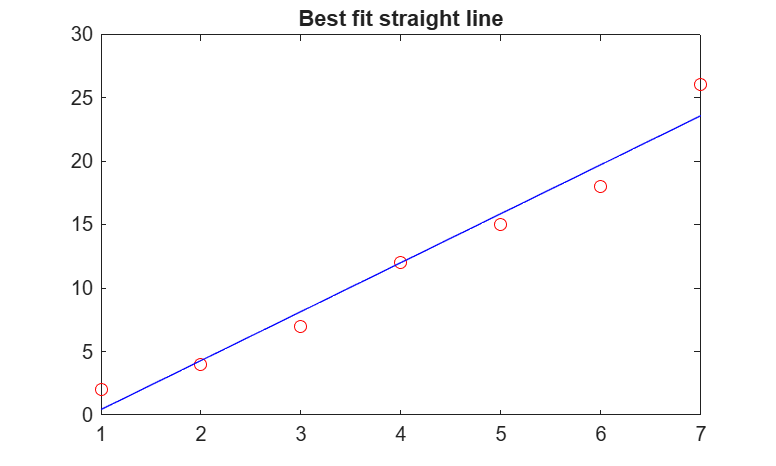


hold on
fplot(stline, [min(x1) max(x1)], 'b')
title('Best fit straight line')

%
% fitting a cubic polynomial
x2 = [1 2 3 4 5 6 7 8 9]';
y2 = [1 5 8 4 2 3 6 10 15]';
n = length(x2);
A2 = ones(n, 4);
A2(:,1) = x2.^3; % dot means coordinate by coordinate
A2(:,2) = x2.^2;
A2(:,3) = x2

A2 =      1     1     1     1
     8     4     2     1
    27     9     3     1
    64    16     4     1
   125    25     5     1
   216    36     6     1
   343    49     7     1
   512    64     8     1
   729    81     9     1


A2T = A2';
b2 = y2;
% Gauss equation
A2TA2 = A2T*A2;
A2Tb2 = A2T*b2;
%solving the system
sol2 = A2TA2\A2Tb2

sol2 =     0.1650
   -2.1696
    8.4750
   -4.7937


c(1) = sol2(1);
c(2) = sol2(2);
c(3) = sol2(3);
c(4) = sol2(4);
%symbolic display
syms t
cubic = c(1)*t^3+c(2)*t^2+c(3)*t+c(4)

$$cubic = \frac{1486036240680949\,t^{3}}{9007199254740992}-\frac{4885398297078173\,t^{2}}{2251799813685248}+\frac{2385497042882365\,t}{281474976710656}-\frac{5397170982005511}{1125899906842624}$$

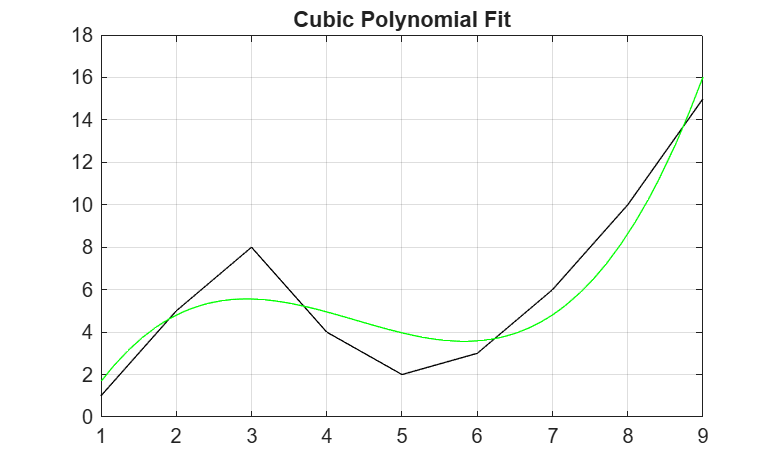

figure
plot(x2, y2, 'k')
% Plot the cubic polynomial fit
hold on
fplot(cubic, [min(x2) max(x2)], 'g')
title('Cubic Polynomial Fit')
grid on